# Lambert Marte Giove

lambert_phasing per trovare t/t_H plausibile

global mu
mu = 132712440018

mu = 1.3271e+11

t0 = datetime(2024, 05, 23)

t0 = datetime
   23-May-2024


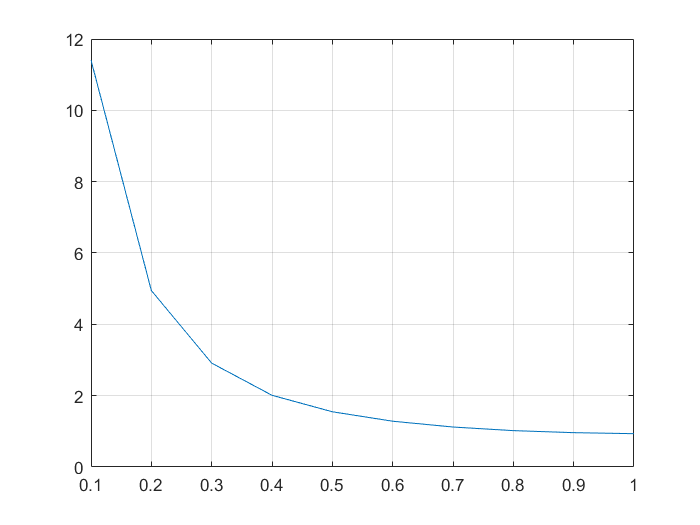

lambert_phasing(4, 5, t0)

Prova con i dati di Lorenzo Incerpi: 

data di partenza da Terra : 29/05/2022

data incontro con Marte : 26/08/2022

data arrivo Giove : 26/08/2024

%cerco R1, vettore posizione di Marte alla data di partenza
%[~, r1, ~, ~] = planet_elements_and_sv(4, 22, 08, 26, 00, 00, 00)
%cerco R2, vettore posizione di Giove alla data di arrivo
%[~, r2, ~, ~] = planet_elements_and_sv(5, 28, 08, 26, 00, 00, 00)

%Lambert Marte-Giove con questi dati
%t = 6*365*24*60*60 
%[V1, V2] = lambert(r1, r2, t, 'pro')

%Calcolo parametri dell'orbita di trasferimento trovata con Lambert
%coe = coe_from_sv(R1,V1,mu)

## Dal grafico decido di usare t/t_H = 0.65. In corrispondenza di esso, deltaV_lambert/deltaV_hohmann è 2.87 (che ci sembra ragionevole)

[deltaV_h, deltaT_h] = hohmann_transfer(4, 5)

deltaV_h = 0.4207

deltaT_h = 9.7319e+07

%t = deltaT_h*0.65 %sono 2 anni
t = 4*365*60*60*24

t = 126144000

%cerco R1, vettore posizione di Marte alla data di arrivo
[~, R1, ~, ~] = planet_elements_and_sv(4, 22, 08, 26, 00, 00, 00)

R1 = 	1.0e+08 *

   -1.3393   -1.8394    0.0017


%cerco R2, vettore posizione di Giove alla data di arrivo
[~, R2, ~, ~] = planet_elements_and_sv(5, 28, 08, 26, 00, 00, 00)

R2 = 	1.0e+08 *

    6.1204   -4.2940   -0.1348


[V1, V2] = lambert(R1, R2, t, 'pro')

V1 =     4.9988  -29.4656   -0.3696


V2 =    -1.3829    8.9204    0.1099


%estraggo parametri orbitali
coe = coe_from_sv(R2,V2,mu)

coe = 	1.0e+09 *

    4.8666    0.0000    0.0000    0.0000    0.0000    0.0000    0.4853


# Flyby su Marte

Ora andando a ritroso proviamo a fare il flyby